# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

姓名：                 学号：                 专业：               

## 实验一 时域离散信号和时域离散系统 

## 一、实验目的

- 掌握求解离散时间系统冲激响应和阶跃响应程序的编写方法，了解常用子函数

- 掌握应用线性卷积求解离散时间系统相应的基本方法

- 掌握Matlab求解离散时间系统响应的基本方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

## 四、实验所用MATLAB函数

（列出实验中需要用到的MATLAB函数并简述其功能）

## 五、实验内容、方法、代码与结果

### **题目1**：用MATLAB编程，实现以下信号序列：

### （1）$\[{{x(n) = \delta (n + 3) + 2\delta (n - 4),}}\left( {{\rm{ - 5 < n < 5}}} \right)\]$；

### （2）$\[{{x(n) = u(n - 2) + u(n + 2),}}\left( {{\rm{ - 5 < n < 5}}} \right)\]$；

### （3）已知$\[{{{x}}_{{1}}}{{(n) = }}{{{e}}^{{{ - n/16}}}}\]$，$\[{{x}_2}{{(n) = 5sin(2\pi n/10)}}\]$试显示$\[{{{x}}_{{1}}}{{(n) \times }}{{{x}}_{{2}}}{{(n)}}\]$在$\[{\textbf{0 < \textit{n} < 24}}\]$区间的波形。

**解答5**：

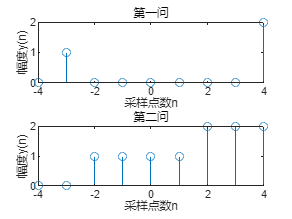

% Insert your code here
n = -4:4;
x1 =(n == -3)+2*(n==4);
x2 = (n>=-2)+(n>=2);
subplot(2,1,1);
stem(n,x1,'o-'); %%(1)
xlabel('采样点数n');
ylabel('幅度y(n)');
title('第一问');
subplot(2,1,2);
stem(n,x2,'o-'); %%(2)
xlabel('采样点数n');
ylabel('幅度y(n)');
title('第二问');

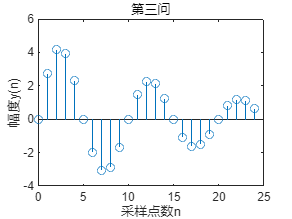

%%%%%(3)%%%%%
n = 0:24;
x1n = exp(-n/16);
x2n = 5*sin(2*pi*n/10);
X = x1n.*x2n;
figure;
stem(n,X,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('第三问');

### **题目2**：已知一个系统：$H(z)=\frac{1}{2} \frac{1+3z^{-1}+3z^{-2}+z^{-3}}{3+z^{-2}}$，（1）画出系统单位冲激响应和单位阶跃响应；（2）画出系统的输入序列$x(n)=R_5 (n)$的响应。

**解答4**：

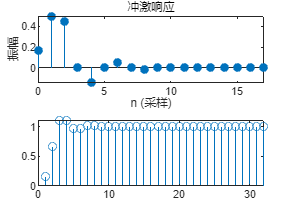

% Insert your code here
b = [1/6 1/2 1/2 1/6];
a = [1 0 1/3 0];
subplot(2,1,1);
impz(b,a);
subplot(2,1,2);
y = dstep(b,a,32);
stem(y);

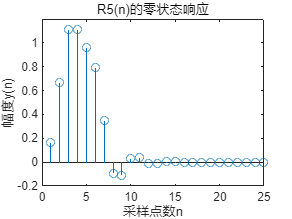

Xn = (n>=0 & n<5);
%Xn = rectwin(5)
Yn = filter(b,a,Xn);
figure;
stem(Yn,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title("R5(n)的零状态响应");

### **题目3**：编写MATLAB程序，已知离散线性时不变系统的系统函数，分别用impz和dstep子函数、filtic和filter子函数两种方法求解系统函数的冲激响应和阶跃响应:

### (1)$H(z)=\frac{1-0.5z^{-2}}{1-z^{-1}+z^{-2}+0.25z^{-4}}$

### (2)$H(z)=1+0.5z^{-1}-0.5z^{-2}-z^{-3}-0.5z^{-4}+z^{-5}$

**解答7**：

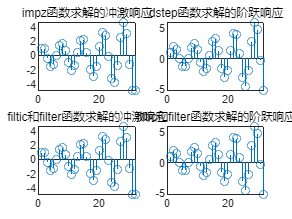

% Insert your code here
%%%(1)%%%
b1 = [1 0 -0.5 0 0];
a1 = [1 -1 1 0 0.25];
figure;
subplot(2,2,1);
hn = impz(b1,a1,32);
stem(hn);
title('impz函数求解的冲激响应');
subplot(2,2,2);
yn = dstep(b1,a1,32);
stem(yn);
title('dstep函数求解的阶跃响应');

n = 0:31;
subplot(2,2,3);
Xn = [1,zeros(1,31)];
Yn = filter(b1,a1,Xn);
stem(Yn);
title('filtic和filter函数求解的冲激响应');
subplot(2,2,4);
Xn = (n>=0);
Yn = filter(b1,a1,Xn);
stem(Yn); 
title('filtic和filter函数求解的阶跃响应');

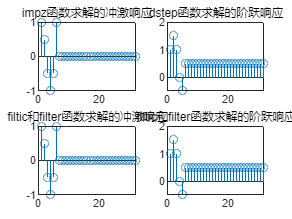


%%%(2)%%%
b2 = [1 0.5 -0.5 -1 -0.5 1];
a2 = [1 0 0 0 0 0];
figure;
subplot(2,2,1);
hn = impz(b2,a2,32);
stem(hn);
title('impz函数求解的冲激响应');
subplot(2,2,2);
yn = dstep(b2,a2,32);
stem(yn);
title('dstep函数求解的阶跃响应');
subplot(2,2,3);
Xn = [1,zeros(1,31)];
Yn = filter(b2,a2,Xn);
stem(Yn);
title('filtic和filter函数求解的冲激响应');
subplot(2,2,4);
Xn = (n>=0);
Yn = filter(b2,a2,Xn);
stem(Yn);
title('filtic和filter函数求解的阶跃响应');

### **题目4**：编写MATLAB程序，已知一个系统的差分方程为y(n)=0.7y(n-1)+2x(n)-x(n-2)，试求此系统的输入序列x(n)=u(n-3)的响应。

**解答4**：

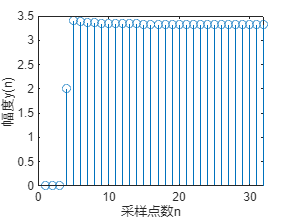

% Insert your code here
b = [2 0 -1];
a = [1 -0.7 0];
Xn = (n>=3);
Yn = filter(b,a,Xn);
figure;
stem(Yn,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');

### **题目5**：编写MATLAB程序，已知一个LSI系统的差分方程表示式为y(n)-0.5y(n-1)+y(n-6)-0.5y(n-7)=x(n)-x(n-1)+x(n-2)，满足初

### 始条件y(-1)=0，x(-1)=0，试用dlsim和filter两种方法求此系统的输入序列x(n)为下列信号时的响应。

### 1.$\mathbf{x}(\mathbf{n})=\mathbf{u}(\mathbf{n}-3)$

### 2.$\mathbf{x}(\mathbf{n})=\delta (\mathbf{n})-\delta (\mathbf{n}-5)$

### 3.$\mathbf{x}(\mathbf{n})=e^{0\ldotp 1\mathbf{n}} \mathbf{u}(\mathbf{n}-3)$

**解答5**：

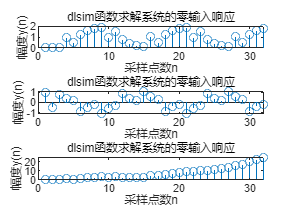

% Insert your code here
b = [1 -1 1 0 0 0 0 0];
a = [1 -0.5 0 0 0 0 1 -0.5];
n  =0:31;
x1 = (n>=3);
x2 = (n==0) - (n==5);
x3 = exp(0.1*n).*(n>=3);
%初始条件y（-1）= 0，x(-1) = 0
%%dlsim函数求解系统的零输入响应
subplot(3,1,1);
Y = dlsim(b, a, x1);
stem(Y,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('dlsim函数求解系统的零输入响应');
subplot(3,1,2);
Y= dlsim(b, a, x2);
stem(Y,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('dlsim函数求解系统的零输入响应');
subplot(3,1,3);
Y = dlsim(b, a, x3);
stem(Y,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('dlsim函数求解系统的零输入响应');

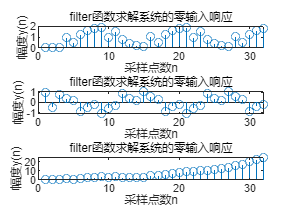


%filter函数求解系统的零输入响应
figure;
subplot(3,1,1);
Y = filter(b, a, x1);
stem(Y,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('filter函数求解系统的零输入响应');
subplot(3,1,2);
Y= filter(b, a, x2);
stem(Y,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('filter函数求解系统的零输入响应');
subplot(3,1,3);
Y = filter(b, a, x3);
stem(Y,'o-');
xlabel('采样点数n');
ylabel('幅度y(n)');
title('filter函数求解系统的零输入响应');

### **题目6**：一个LSI系统的系统函数表示式为：

### 
$$H(z)=\frac{0\ldotp 187632+0\ldotp 241242z^{-1} +0\ldotp 241242z^{-2} +0\ldotp 187632z^{-3} }{1-0\ldotp 602012z^{-1} +0\ldotp 495684z^{-2} -0\ldotp 035924z^{-3} }$$


### 满足初始条件：y(-1)=5，y(-2)=5，试用filtic和filter子函数求此系统的输入序列为下列信号时的零输入、零状态及完全响应。

### 1.$\mathbf{x}(\mathbf{n})=\delta (\mathbf{n}-3)$

### 2.$\mathbf{x}(\mathbf{n})={\mathbf{R}}_5 (\mathbf{n})$

### 3.$\mathbf{x}(\mathbf{n})=\cos \frac{2\pi }{3}\mathbf{n}+\sin \frac{3\pi }{10}\mathbf{n}$

**解答6**：

% Insert your code here
b = [0.187632 0.241242 0.241242 0.187632];
a = [1 -0.602012 0.495684 -0.035924];
